## Homework 4: Space Vehicles and Orbital Dynamics

#### Authors:

- Jaume Manresa Rigo (100461930)

- Jorge Cortés de Jesús (100428594)

clear; clc; 
close all;

### Introduction

The objective of this homework is to explore a family of Lyapunov closed periodic orbits contained in the *xy* plane of the Circular Restricted Three-Body Problem (CR3BP) with $\mu^{\ast } =0\ldotp 001$, around the Lagrange libration point $L_1$. This is a very relevant problem in astrodynamics for interplanetary spaceflights and general celestial mechanics. CR3BP assumes that: 

- $m^{P_1 } >m^{P_2 } \gg m^{P_3 }$. Thus, the motion of $P_1$ and $P_2 \;$(primaries) is assumed to be unaffected by $P_3$.

- The primaries orbit the center of mass in circles, i.e. the motion of the primaries is an unperturbed 2BP.

mustar = 0.001;

The analysis will be performed in the synodic (rotating) reference frame. 

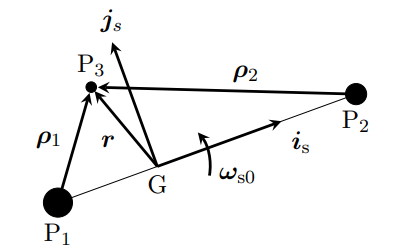

The full nonlinear equations will be employed.

$\ddot{x} =-\frac{1-\mu^{\ast } }{\rho_1^3 }\left(x+\mu^{\ast } \right)-\frac{\mu^{\ast } }{\rho_2^3 }\left(x+\mu^{\ast } -1\right)+x+2\dot{y}$,

$\ddot{y} =-\frac{1-\mu^{\ast } }{\rho_1^3 }y-\frac{\mu^{\ast } }{\rho_2^3 }y+y-2\dot{x}$,

Where $\rho_1^2 ={\left(x+\mu^{\ast } \right)}^2 +y^2 +z^2$, and $\rho_2^3 ={\left(x+\mu^{\ast } -1\right)}^2 +y^2 +z^2$ are the normalized magnitude of the distance vector from P1 and P2 to P3, respectively.

### Part (a)

To begin, the position of $L_1$ will be obtained. From theory, it is known that this specific point, along with $L_2$ and $L_3$, will be collinear, which means that its position will lie in the x-axis. Furthermore, knowing that a Lagrange point is an equilibrium position and taking the first equation the expression for $x_{L_1 }$ is found.


$$0=\frac{1-\mu^{\ast } }{\rho_1^3 }\left(x_{L_1 } +\mu^{\ast } \right)-\frac{\mu^{\ast } }{\rho_2^3 }\left(x_{L_1 } +\mu^{\ast } -1\right)+x_{L_1 }$$


where $\rho_1 =\left|x_{L_1 } +\mu^{\ast } \right|$ and $\rho_2 =\left|x_{L_1 } +\mu^{\ast } -1\right|$. 

To computation of $x_{L_1 }$ will utilize the bult-in Matlab function *fzero. *It is essential to carefully select an initial guess ($x_0$) to ensure that the solver actually finds $x_{L_1 }$ instead of $x_{L_2 }$ or $x_{L_3 }$. Given that $L_1$ will be located between $P_1$ and $P_2 \;$, the non-dimensional position of both bodies is calculated, finding the mean value and using it as $x_0$.


$$x_1 =-\mu^{\ast } ;\;\;\;\;\;x_2 =1-\mu^{\ast }$$



$$x_0 =\frac{x_1 +x_2 }{2}$$


x1 = -mustar;
x2 = 1-mustar;
x0 = (x1+x2)/2;

f = @(xL1) -(1-mustar)/abs(xL1+mustar)^3*(xL1+mustar) - mustar/abs(xL1-1+mustar)^3*(xL1-1+mustar) + xL1;
xL1 = fzero(f,x0);

fprintf('The position of the first Lagrange libration point (L1) is %f ',xL1);

The position of the first Lagrange libration point (L1) is 0.931287 

### Part (b)

### Part (c)

### Part (d)

A

### Part (e)

A

### Conclusion and Remarks

A